# Analysis of the Data from Lymphoid Lineage Blood Differentiation

clearvars
addpath(genpath('../'))

## Pre-processing the data

load data_mpp.mat
data = data';
[N_cell,~] = size(data);

## Estimation of Cluster Number

par.choice_distance = 'cosine';
out = EstClusterNum(data,par);

Computed P-values 500 of 2018 datapoints...
Computed P-values 1000 of 2018 datapoints...
Computed P-values 1500 of 2018 datapoints...
Computed P-values 2000 of 2018 datapoints...
Mean value of sigma: 0.2594
Minimum value of sigma: 0.17169
Maximum value of sigma: 0.43467


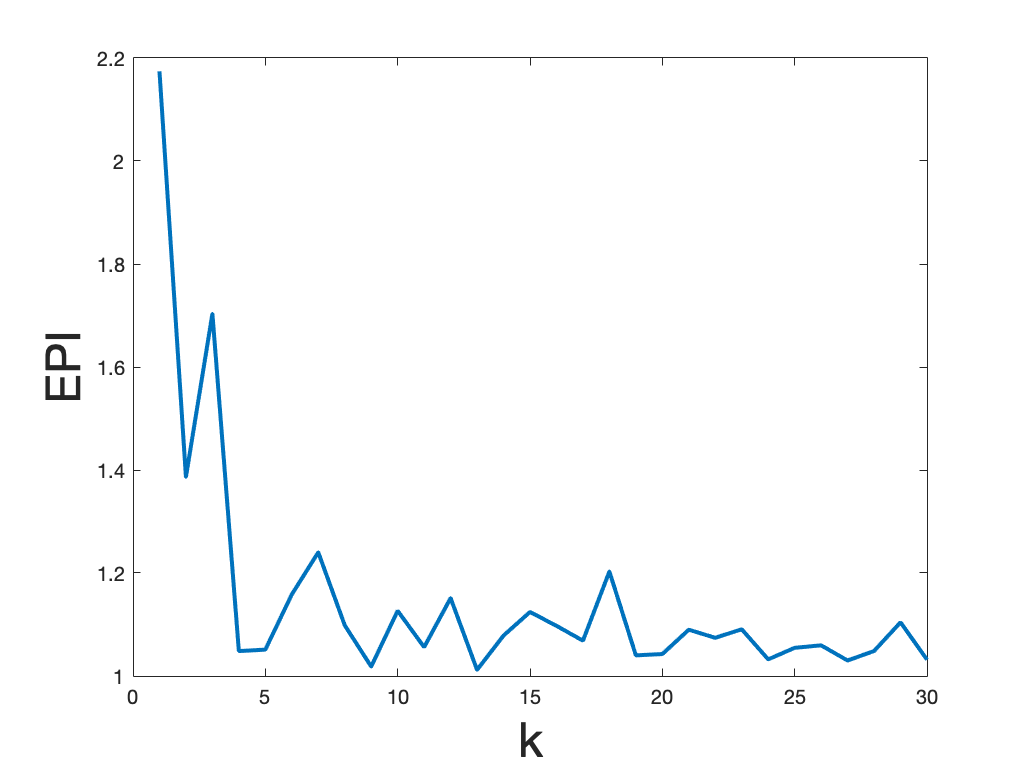

plot(out.ratio(1:30),'linewidth',2.0)
xlabel('k', 'FontSize', 24);
ylabel('EPI', 'FontSize', 24);

## Initial visualization by tSNE

rng(1)
Dist = squareform(pdist (data,'cosine'));
ydata = tsne_d(Dist);

Computed P-values 500 of 2018 datapoints...
Computed P-values 1000 of 2018 datapoints...
Computed P-values 1500 of 2018 datapoints...
Computed P-values 2000 of 2018 datapoints...
Mean value of sigma: 0.1537
Minimum value of sigma: 0.10088
Maximum value of sigma: 0.27062
Iteration 10: error is 49.8475
Iteration 20: error is 47.0807
Iteration 30: error is 46.0238
Iteration 40: error is 45.9552
Iteration 50: error is 45.7846
Iteration 60: error is 45.7518
Iteration 70: error is 45.8181
Iteration 80: error is 45.7725
Iteration 90: error is 45.6994
Iteration 100: error is 2.9944
Iteration 110: error is 2.3854
Iteration 120: error is 2.0264
Iteration 130: error is 1.8718
Iteration 140: error is 1.7827
Iteration 150: error is 1.7229
Iteration 160: error is 1.6801
Iteration 170: error is 1.6469
Iteration 180: error is 1.6207
Iteration 190: error is 1.5994
Iteration 200: error is 1.5818
Iteration 210: error is 1.5667
Iteration 220: error is 1.5537
Iteration 230: error is 1.5423
Iteration 240: e

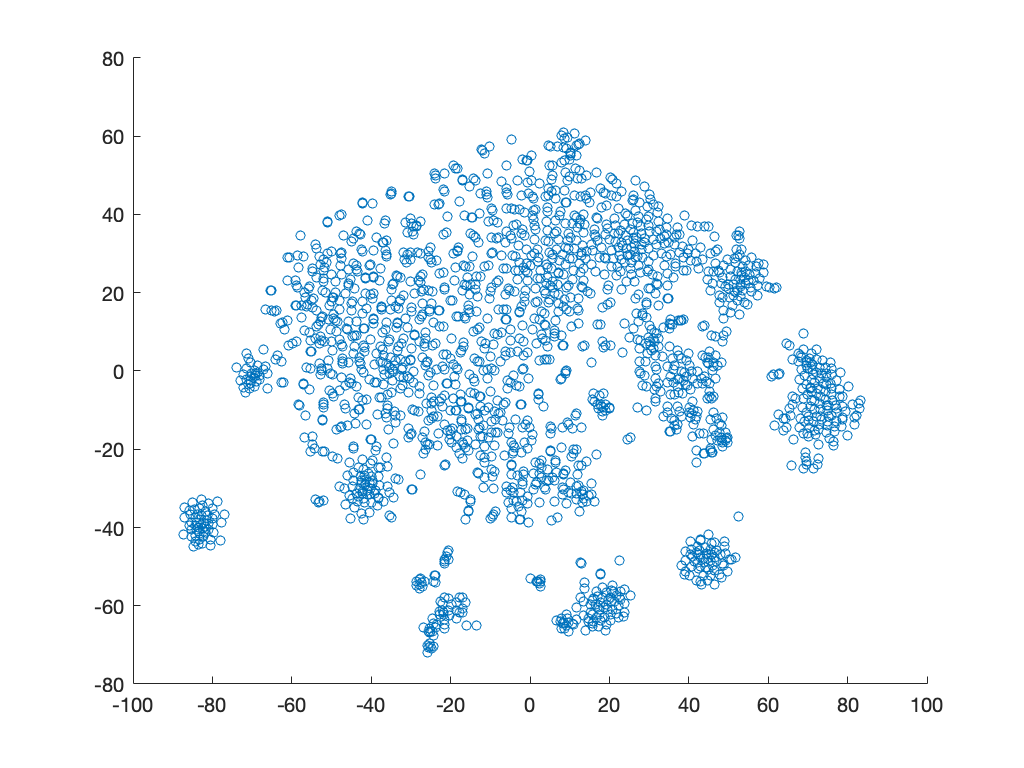

score = ydata;
figure;
scatter(score(:,1),score(:,2),22);

score_tsne = score;

## Show Some Marker Genes

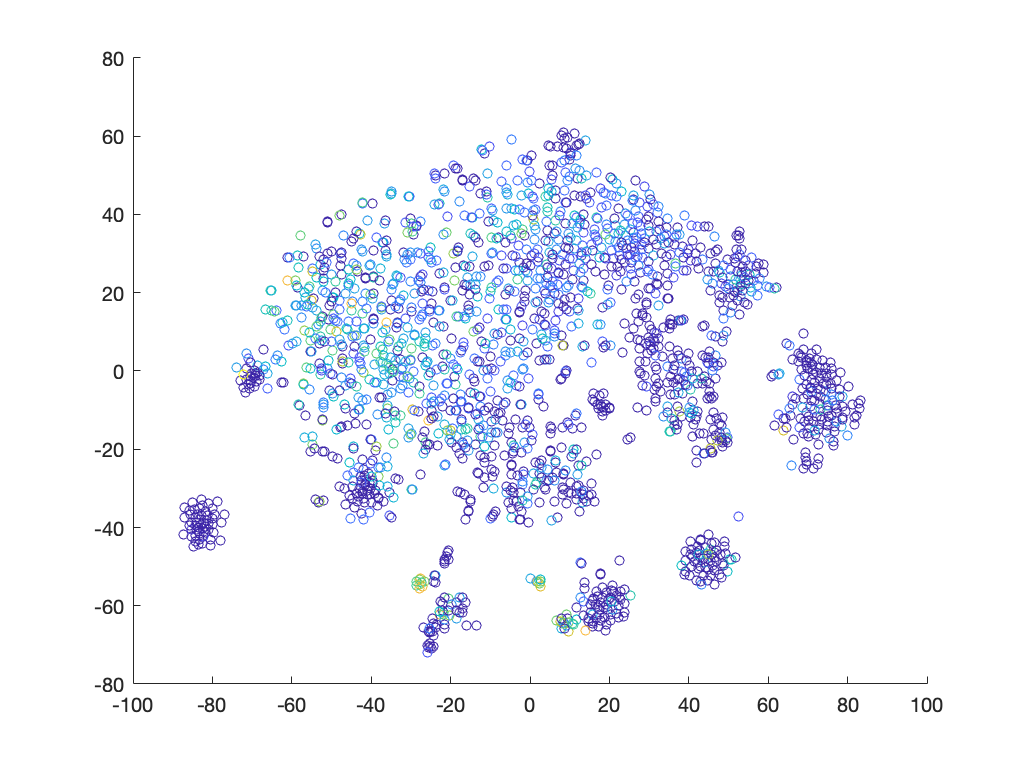

genes_plot = 'Ly6a' ;%% pre-B'Igll1'; %mono Mpo HSC cd34 lp Il7r
Index = find(contains(genes,genes_plot));
genes_expression = data(:,Index(1));
figure;
scatter(score(:,1),score(:,2),22,genes_expression);

%}

## MuTrans Dynamical Analysis of the Single-Cell Data

parameter and option settings

Computed P-values 500 of 2018 datapoints...
Computed P-values 1000 of 2018 datapoints...
Computed P-values 1500 of 2018 datapoints...
Computed P-values 2000 of 2018 datapoints...
Mean value of sigma: 0.25879
Minimum value of sigma: 0.17126
Maximum value of sigma: 0.43398


J_new = 3.9275

J_new = 3.9109

J_new = 3.8908

J_new = 3.8800

J_new = 3.8777

J_new = 3.8764

J_new = 3.8756

J_new = 3.8750

J_new = 3.8746

J_new = 3.8739

J_new = 3.8736

J_new = 3.8735

J_new = 3.8734

J_new = 3.8733

J_new = 3.8734

J_new = 3.9284

J_new = 3.9131

J_new = 3.8965

J_new = 3.8814

J_new = 3.8778

J_new = 3.8760

J_new = 3.8754

J_new = 3.8747

J_new = 3.8739

J_new = 3.8736

J_new = 3.8735

J_new = 3.8734

J_new = 3.8733

J_new = 3.8734

J_new = 3.9284

J_new = 3.9133

J_new = 3.8971

J_new = 3.8818

J_new = 3.8784

J_new = 3.8762

J_new = 3.8755

J_new = 3.8748

J_new = 3.8740

J_new = 3.8737

J_new = 3.8736

J_new = 3.8735

J_new = 3.8733

J_new = 3.8732

J_new = 3.8736

J_new = 3.9285

J_new = 3.9128

J_new = 3.8955

J_new = 3.8800

J_new = 3.8775

J_new = 3.8762

J_new = 3.8753

J_new = 3.8748

J_new = 3.8743

J_new = 3.8737

J_new = 3.8736

J_new = 3.8735

J_new = 3.8734

J_new = 3.8733

J_new = 3.8732

J_new = 3.8731

J_new = 3.8728

J_new = 3.8720

J_new = 3.8713

J_new = 3.8707

J_new = 3.8704

J_new = 3.8703

J_new = 3.8701

J_new = 3.8701

J_new = 3.8701

J_new = 3.9284

J_new = 3.9131

J_new = 3.8965

J_new = 3.8814

J_new = 3.8778

J_new = 3.8760

J_new = 3.8754

J_new = 3.8747

J_new = 3.8739

J_new = 3.8736

J_new = 3.8735

J_new = 3.8734

J_new = 3.8733

J_new = 3.8734

J_new = 3.9491

J_new = 3.9386

J_new = 3.9355

J_new = 3.9331

J_new = 3.9304

J_new = 3.9278

J_new = 3.9249

J_new = 3.9231

J_new = 3.9216

J_new = 3.9204

J_new = 3.9197

J_new = 3.9184

J_new = 3.9174

J_new = 3.9166

J_new = 3.9161

J_new = 3.9152

J_new = 3.9139

J_new = 3.9127

J_new = 3.9116

J_new = 3.9111

J_new = 3.9101

J_new = 3.9094

J_new = 3.9089

J_new = 3.9088

J_new = 3.9086

J_new = 3.9087

J_new = 3.9302

J_new = 3.9140

J_new = 3.8959

J_new = 3.8809

J_new = 3.8781

J_new = 3.8764

J_new = 3.8754

J_new = 3.8748

J_new = 3.8744

J_new = 3.8737

J_new = 3.8736

J_new = 3.8735

J_new = 3.8734

J_new = 3.8733

J_new = 3.8732

J_new = 3.8731

J_new = 3.8728

J_new = 3.8720

J_new = 3.8713

J_new = 3.8707

J_new = 3.8704

J_new = 3.8703

J_new = 3.8701

J_new = 3.8701

J_new = 3.8701

J_new = 3.9285

J_new = 3.9128

J_new = 3.8955

J_new = 3.8800

J_new = 3.8775

J_new = 3.8762

J_new = 3.8753

J_new = 3.8748

J_new = 3.8743

J_new = 3.8737

J_new = 3.8736

J_new = 3.8735

J_new = 3.8734

J_new = 3.8733

J_new = 3.8732

J_new = 3.8731

J_new = 3.8728

J_new = 3.8720

J_new = 3.8713

J_new = 3.8707

J_new = 3.8704

J_new = 3.8703

J_new = 3.8701

J_new = 3.8701

J_new = 3.8701

J_new = 3.9284

J_new = 3.9133

J_new = 3.8971

J_new = 3.8818

J_new = 3.8784

J_new = 3.8762

J_new = 3.8755

J_new = 3.8748

J_new = 3.8740

J_new = 3.8737

J_new = 3.8736

J_new = 3.8735

J_new = 3.8733

J_new = 3.8732

J_new = 3.8736

J_new = 3.9284

J_new = 3.9133

J_new = 3.8971

J_new = 3.8818

J_new = 3.8784

J_new = 3.8762

J_new = 3.8755

J_new = 3.8748

J_new = 3.8740

J_new = 3.8737

J_new = 3.8736

J_new = 3.8735

J_new = 3.8733

J_new = 3.8732

J_new = 3.8736

E_best = 0.5804

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          3.90558                      0.000228
     1           6          3.87904           7381       0.000325  
     2           7          3.84528              1       0.000587  
     3           8          3.83661              1       0.000707  
     4           9          3.81351              1       0.000762  
     5          10          3.80266              1       0.000693  
     6          11          3.79805              1       0.000615  
     7          12          3.79168              1       0.000397  
     8          13           3.7867              1       0.000533  
     9          14          3.78246              1        0.00045  
    10          15          3.77999              1       0.000522  
    11          16          3.77696              1       0.000353  
    12          17          3.77317              

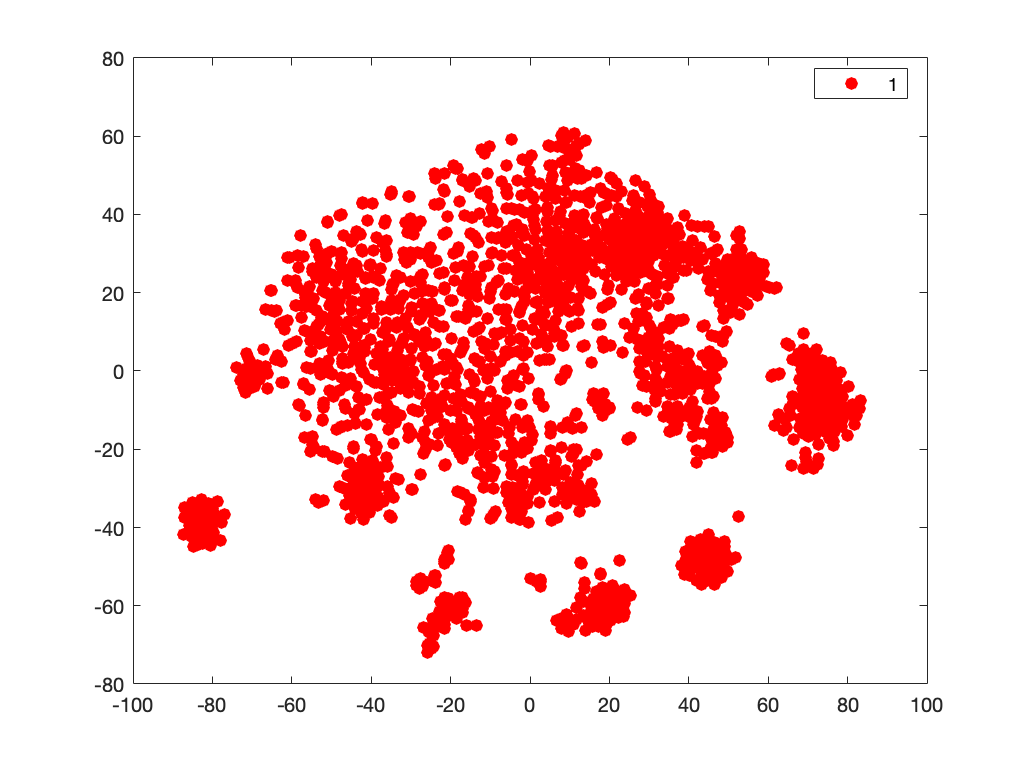

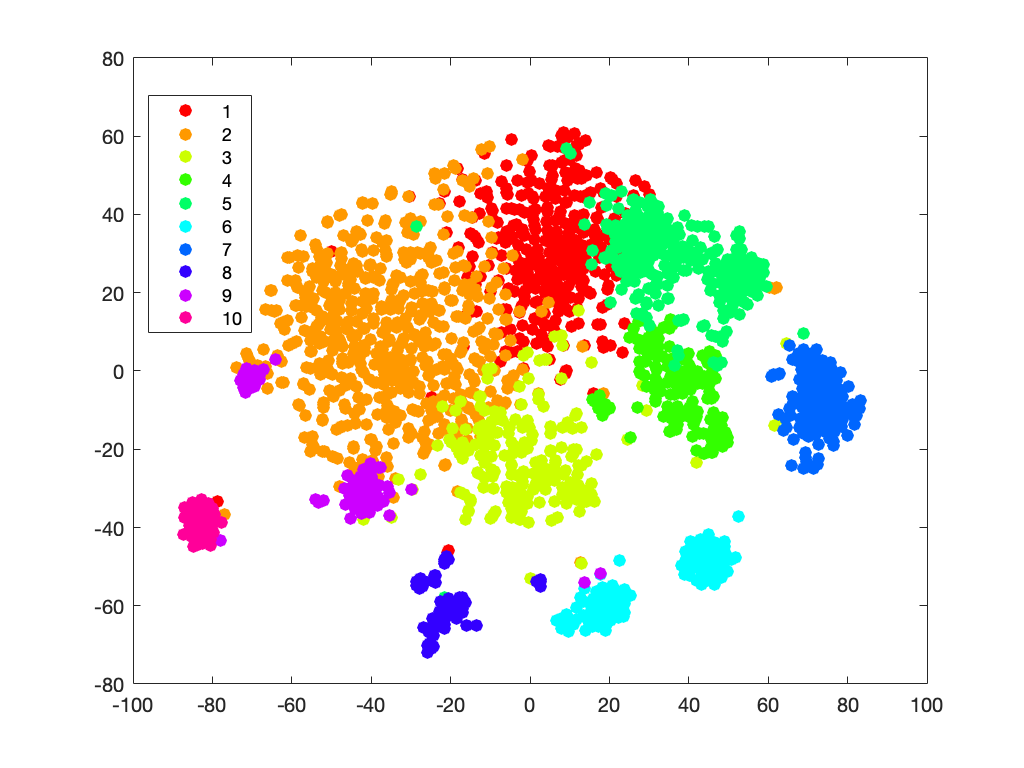

rng(1)
par.initial = 'other';
par.perplex = 800; 
par.K_cluster = 10;
par.trials = 10;
par.alpha_scale = 0.5;
par.weight_scale = true;
par.print_results = true;
par.score = score_tsne;
par.init_score = score_tsne;

% Dynamical Analysis and Output
tic;
Output = DynamicalAnalysis (data, par);

toc;

Elapsed time is 10889.274322 seconds.



class_order = Output.class_order;
data_perm = Output.data_perm;
k = par.K_cluster;
perm_class = Output.perm_class;

## Cell-fate Landscape

embeddings and centers

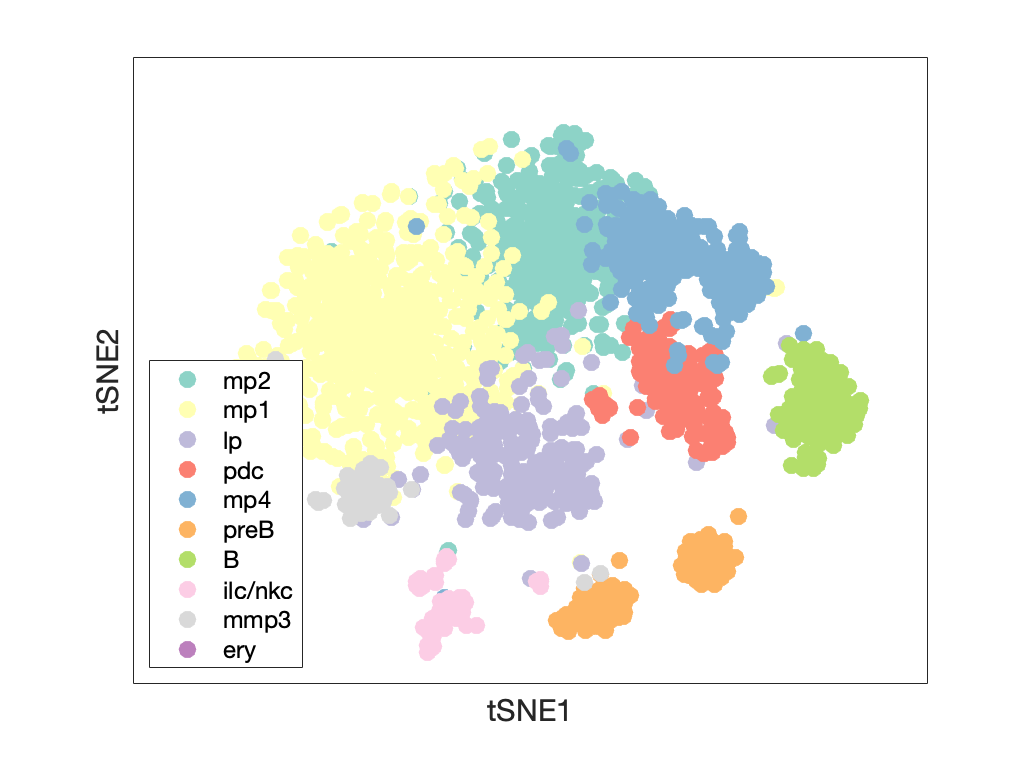

name_cluster = {'mp2','mp1','lp','pdc','mp4','preB','B','ilc/nkc','mmp3','ery'};
colors_cluster = brewermap(k,'set3');
labs_perm = Output.labs_perm;

Output.embedding_2d = score_tsne(perm_class,:);
score_2d = score_tsne(perm_class,:);

figure;
gscatter(score_2d(:,1),score_2d(:,2),class_order,colors_cluster,[],30);
legend(name_cluster,'Fontsize',12,'Location','SouthWest')
set(gca,'xtick',[],'ytick',[]);
xlabel('tSNE1','Fontsize',15)
ylabel('tSNE2','Fontsize',15)

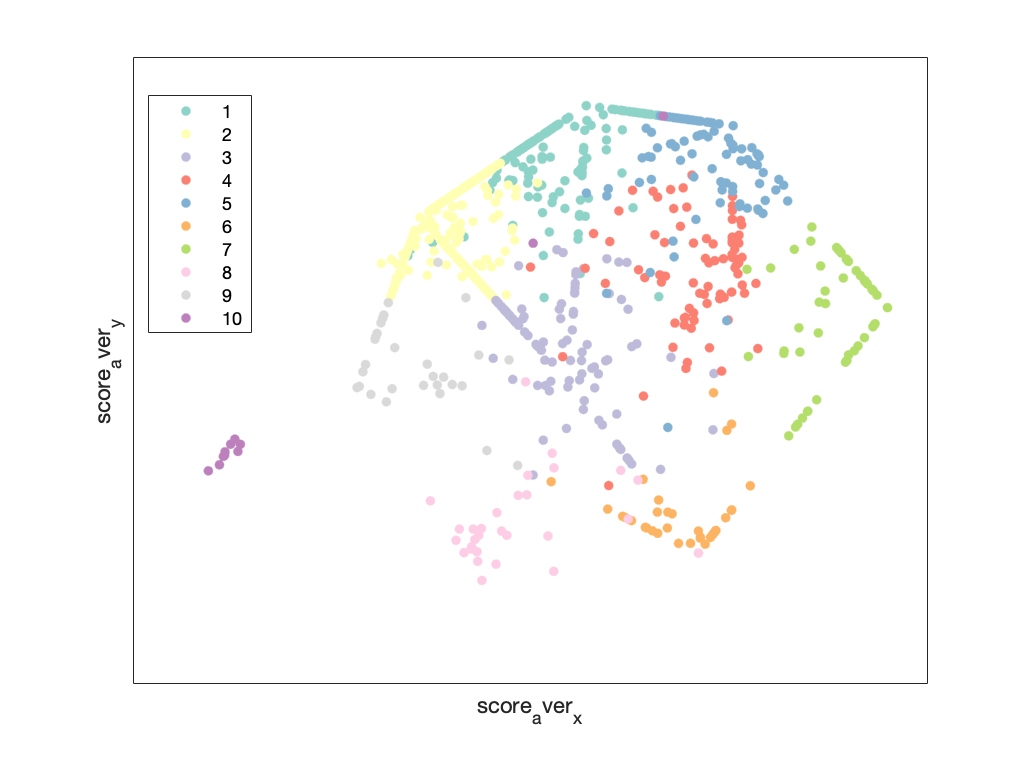

Output.embedding_2d = score_2d;


% construct landscape
par.thresh_calc_center = 0.9;
par.thresh_calc_cov = 0.2;
par.N_mesh = 1000;
par.mksize = 15;
par.scaleaxis = 1.1; 
par.scalevalue = 1.0; 
par.fontsize = 30;
par.alpha = 0.4;

par.plot_label = class_order;
par.legend_text = name_cluster;
par.colors = colors_cluster;
par.color_mixing = true;

land = ConstructLandscape (Output, par);

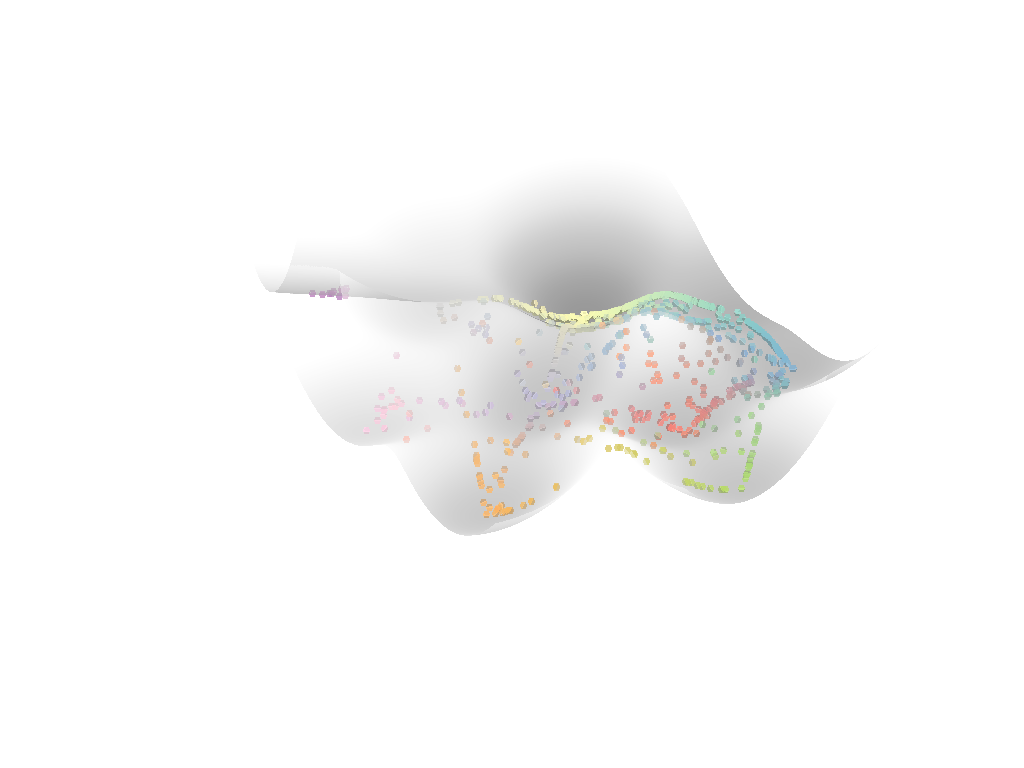

view([49 77])

## Transcendental transition cell and gene analysis

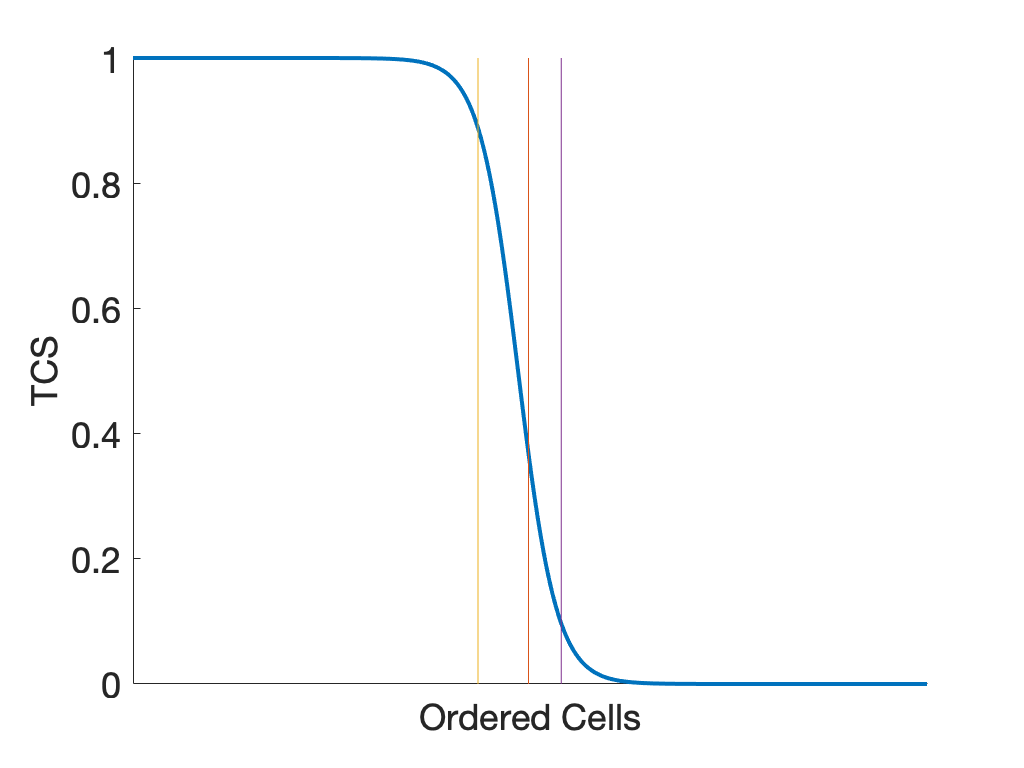

Below is the heatmap of transition genes


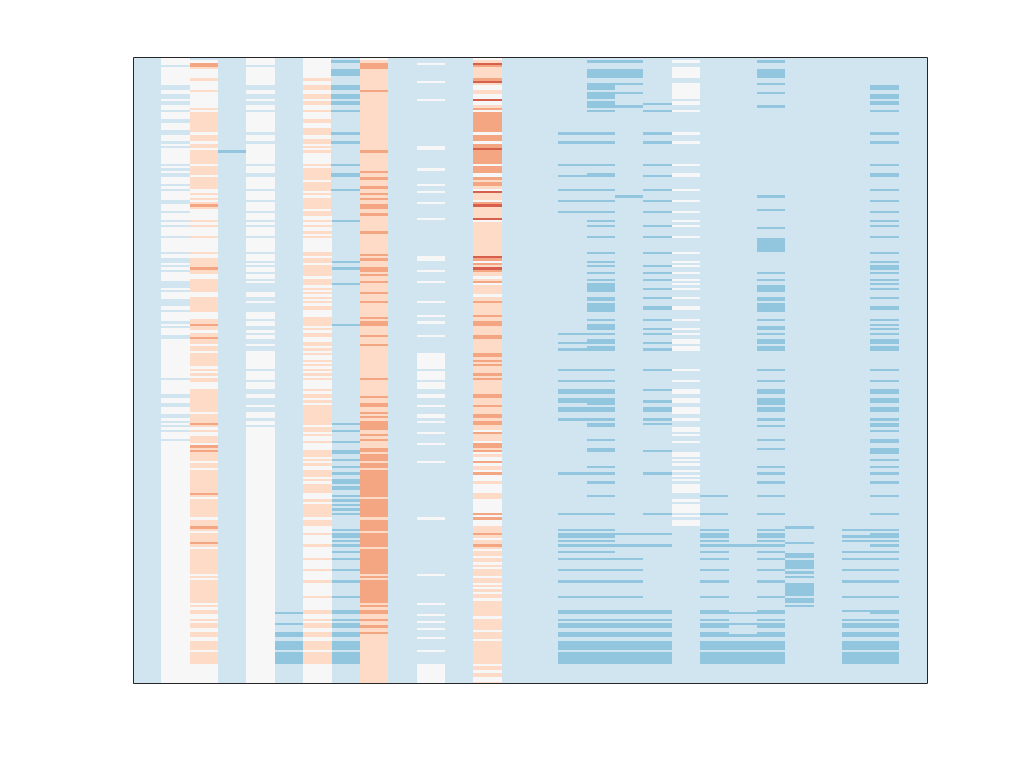

Below is the heatmap of down-regulated MS/IH genes


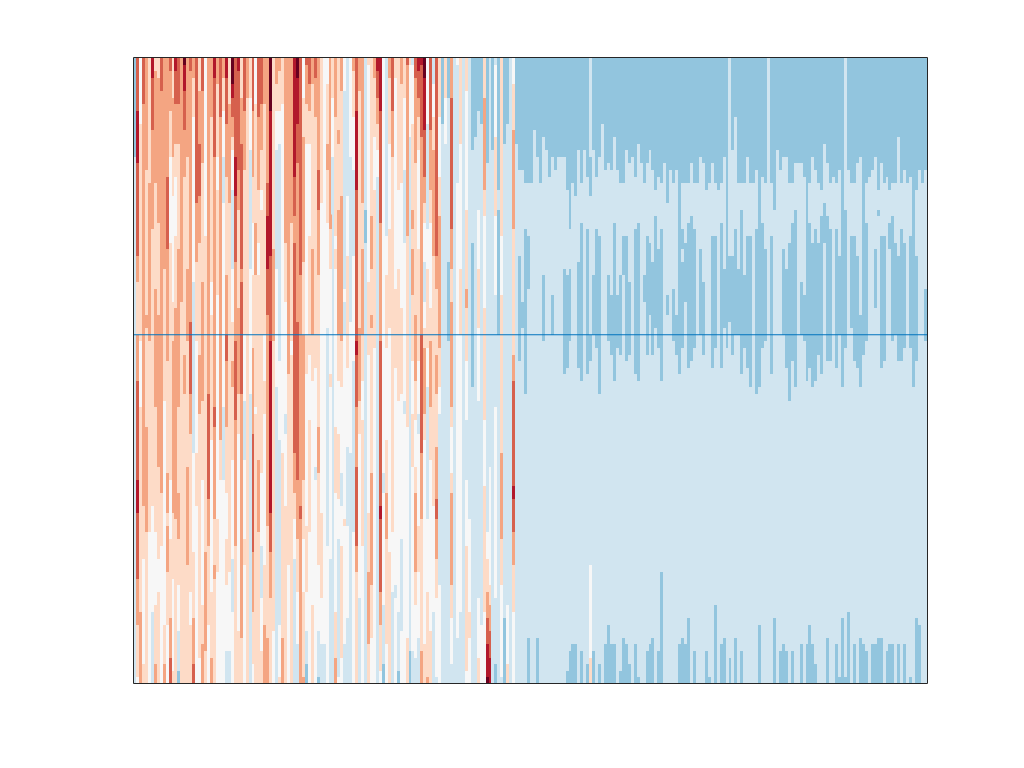

Below is the heatmap of up-regulated MS/IH genes


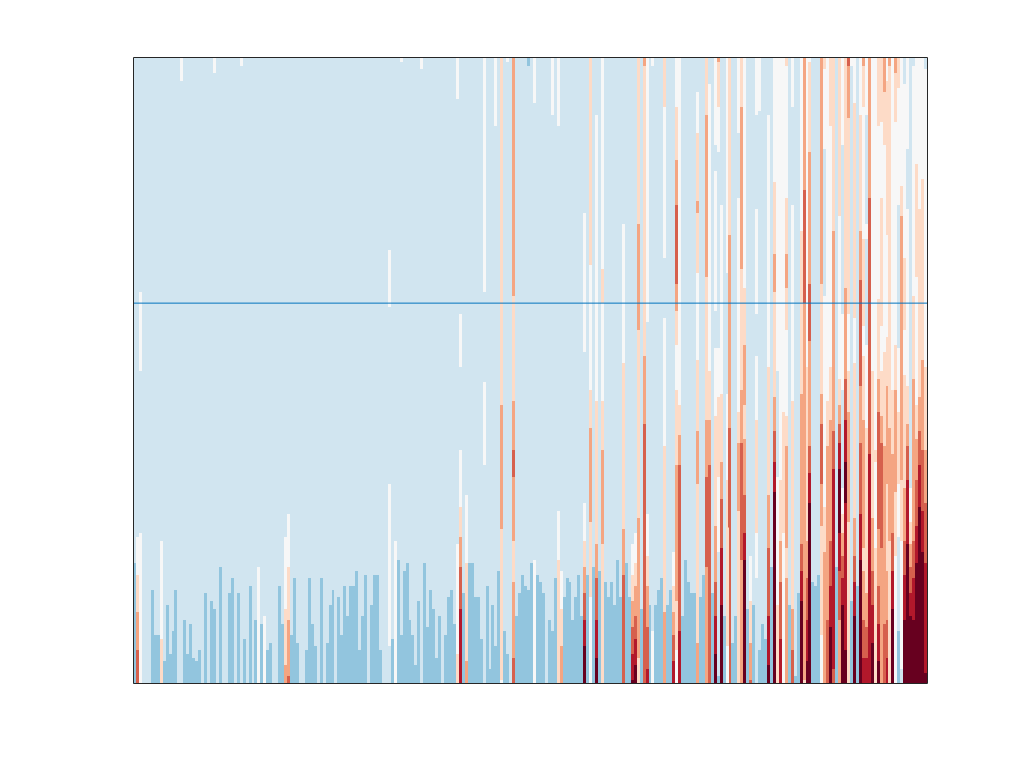

Below is the gradual cell indentity change of the interested process


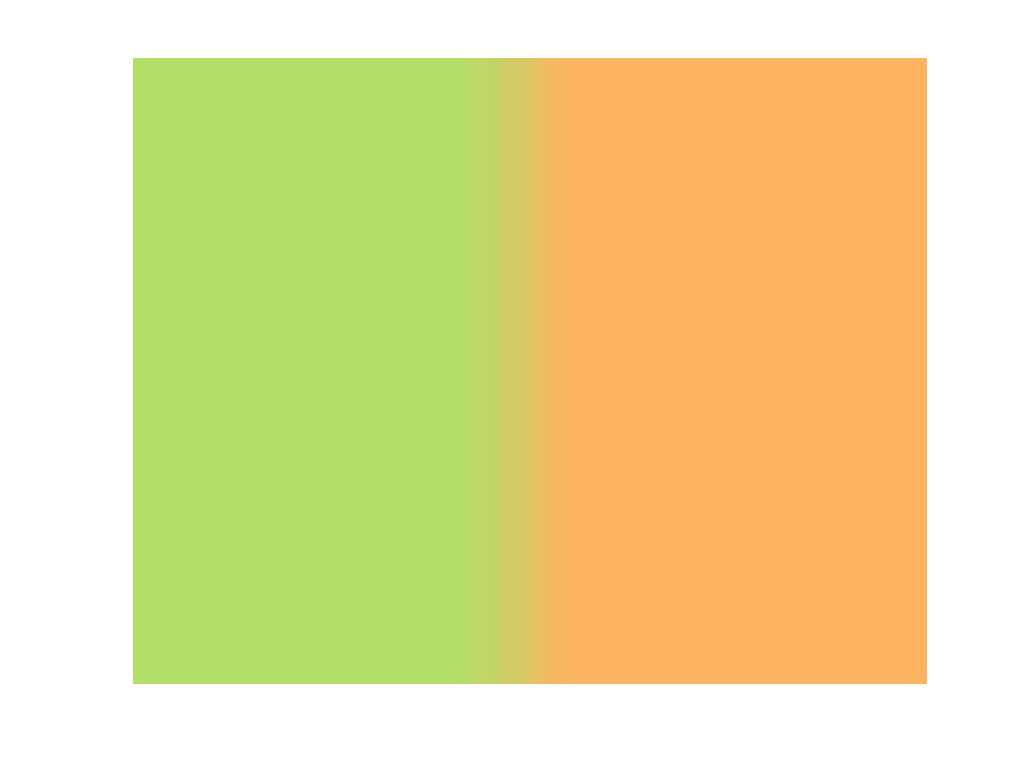

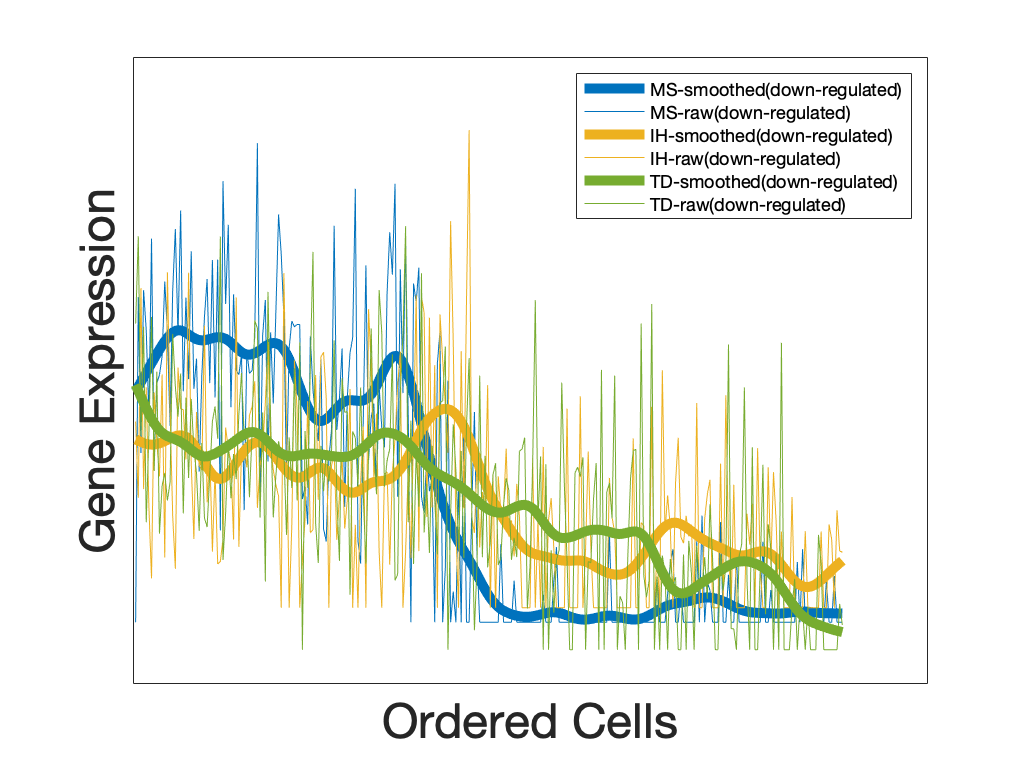

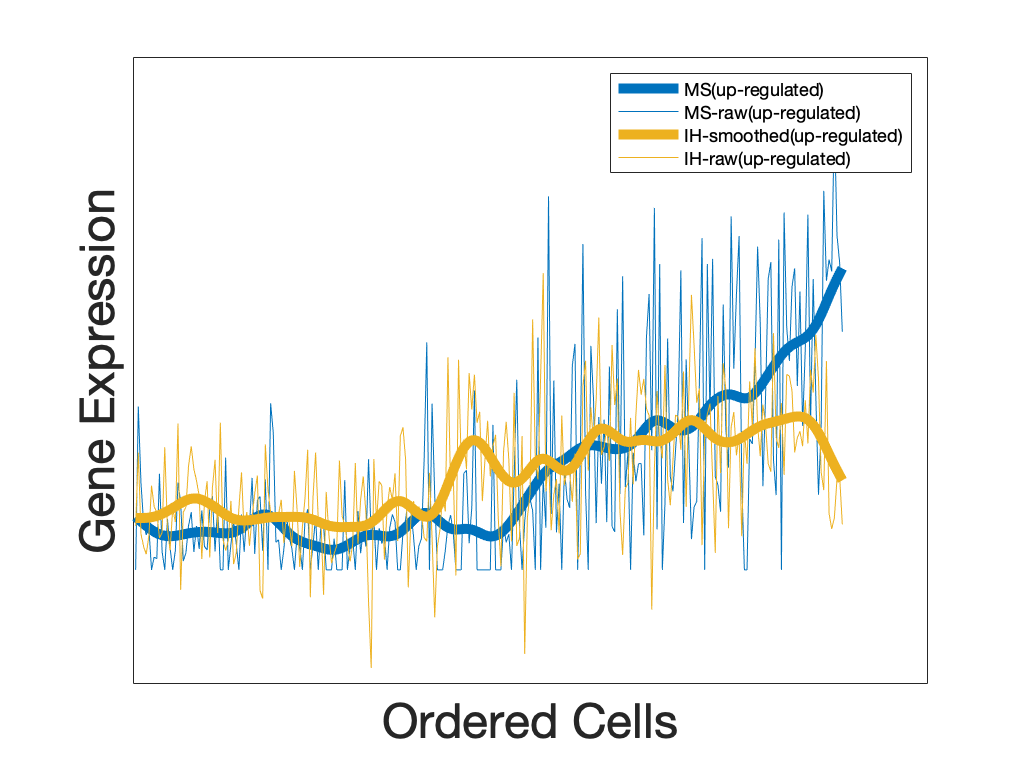

par.genes = genes;
par.true_labs = labs_perm;
par.thresh_otherkeep = 0.3;
par.thresh_de_pvalues = 5e-3;
par.thresh_ms_pvalues = 1e-2;
par.thresh_tcs = 0.4;
par.thresh_td_genes = 0.4;
par.colors = colors_cluster ;
par.L_select_top_genes = 5;
par.flip = false;
par.display_genes_label = false;
par.output_heatmap = true;
% check the state id before preceeding due to possible randomness of
% clustering id. Results unchanged.
out = GeneAnalysis(7, 6, Output,par);

## output other data in Supplementary

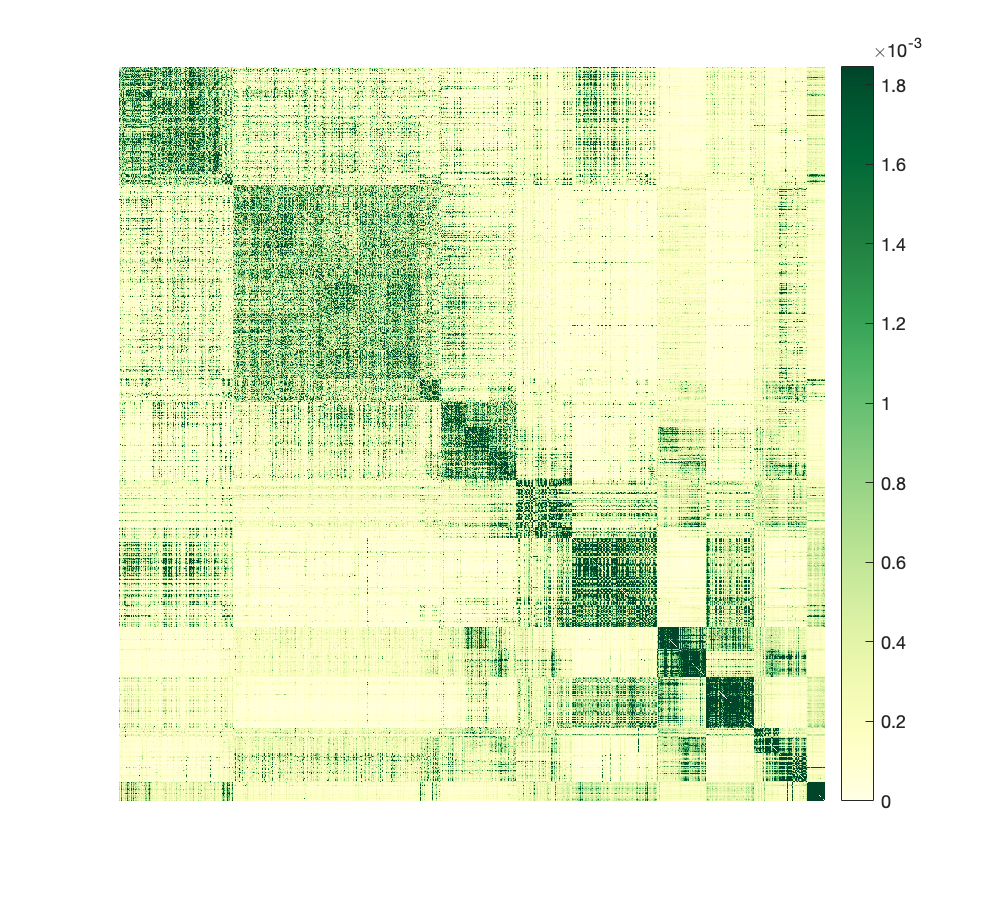

rho_class = Output.rho_class;
perm_class = Output.perm_class;
P_hat = Output.P_hat;
P_appr_perm = Output.P_appr_perm;
P_perm = Output.P_perm;
P_rho = Output.P_rho;
labs_perm = Output.labs_perm;
mu_hat = Output.mu_hat;
k = Output.k;
H = Output.H;

max_P = 0.2* max(max(P_rho));
c_lim = [0 max_P];
cmp = 'ylgn';

figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)
colorbar;

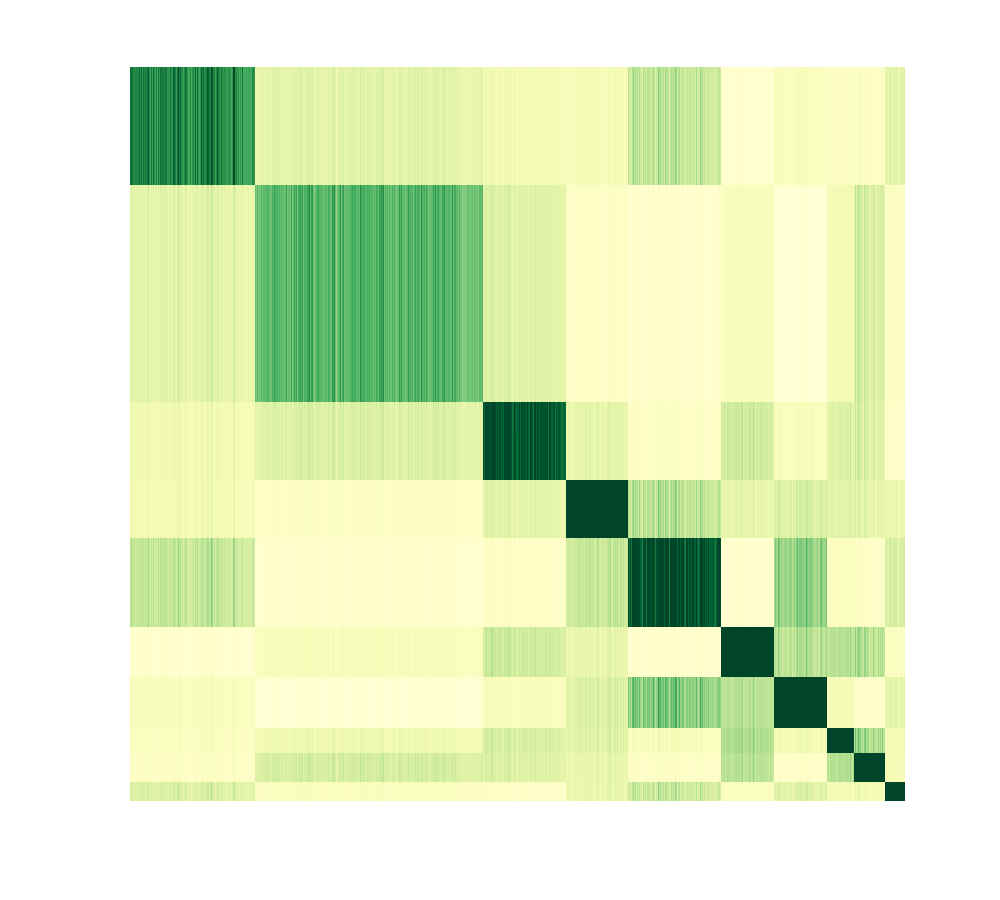



figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_appr_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)

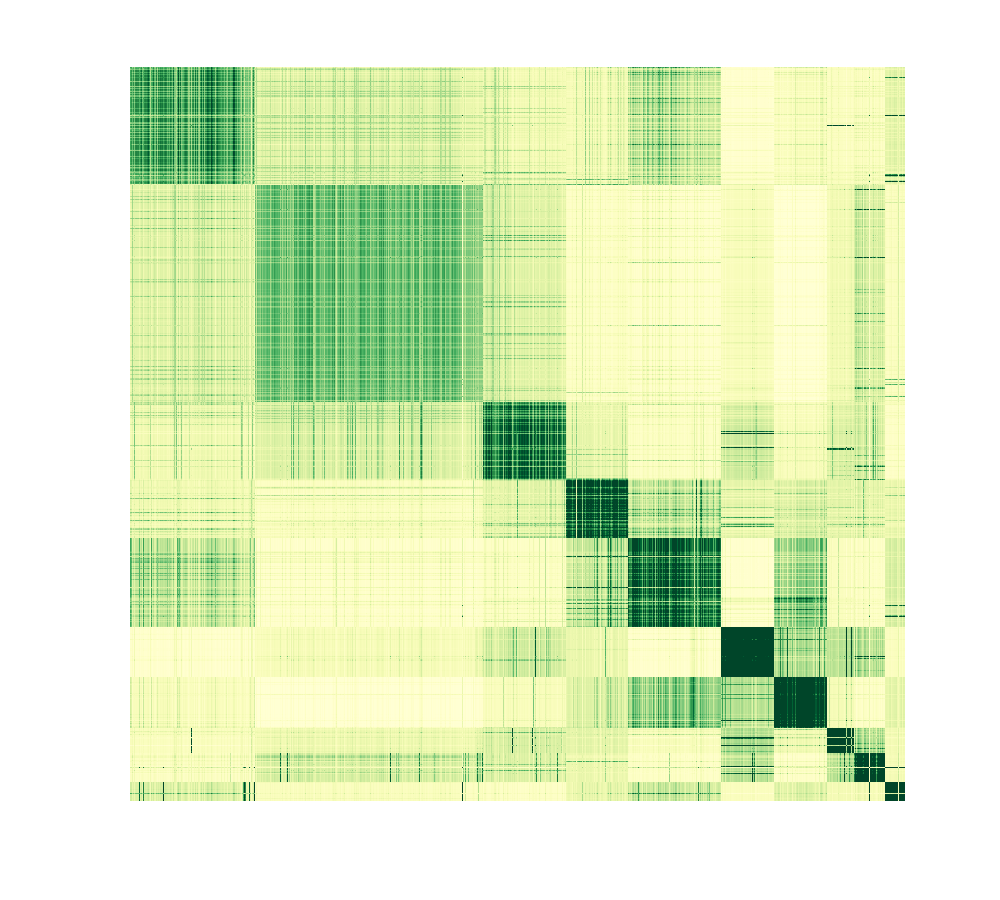

%colorbar;

figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_rho);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)
%colorbar;
box off

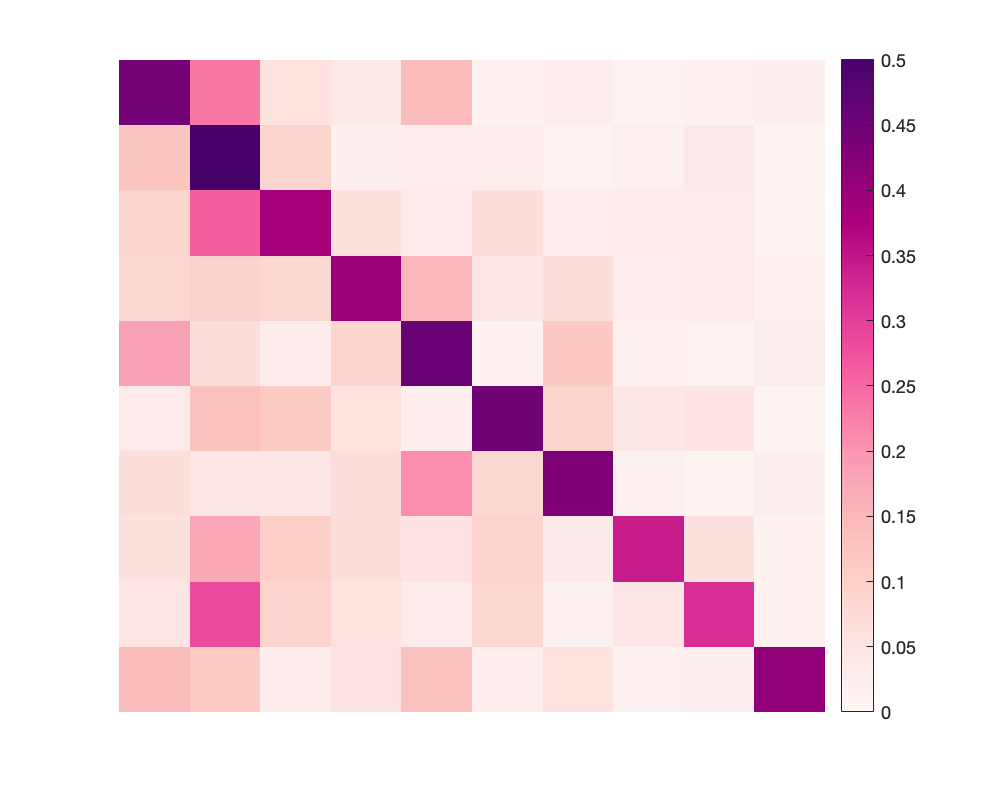


cmp = 'rdpu';
figure('rend','painters','pos',[10 10 500  400])
colormap(brewermap([],cmp))
imagesc(P_hat);
caxis([0 0.5])
axis off
set(gca,'xtick',[],'ytick',[]);
box off
colorbar;

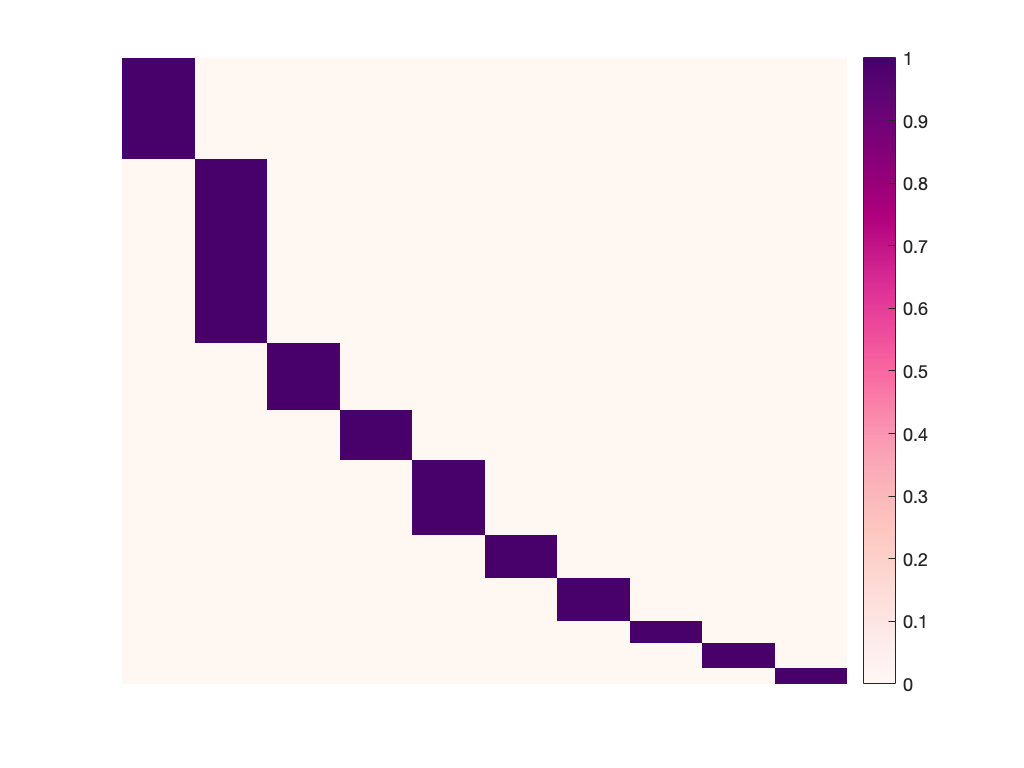


figure;
for id_cluster  = 1:k
member(:,id_cluster) = (class_order == id_cluster)';
end
colormap(brewermap([],cmp))
imagesc(member);
caxis([0 1])
colorbar;
axis off
set(gca,'xtick',[],'ytick',[]);
box off

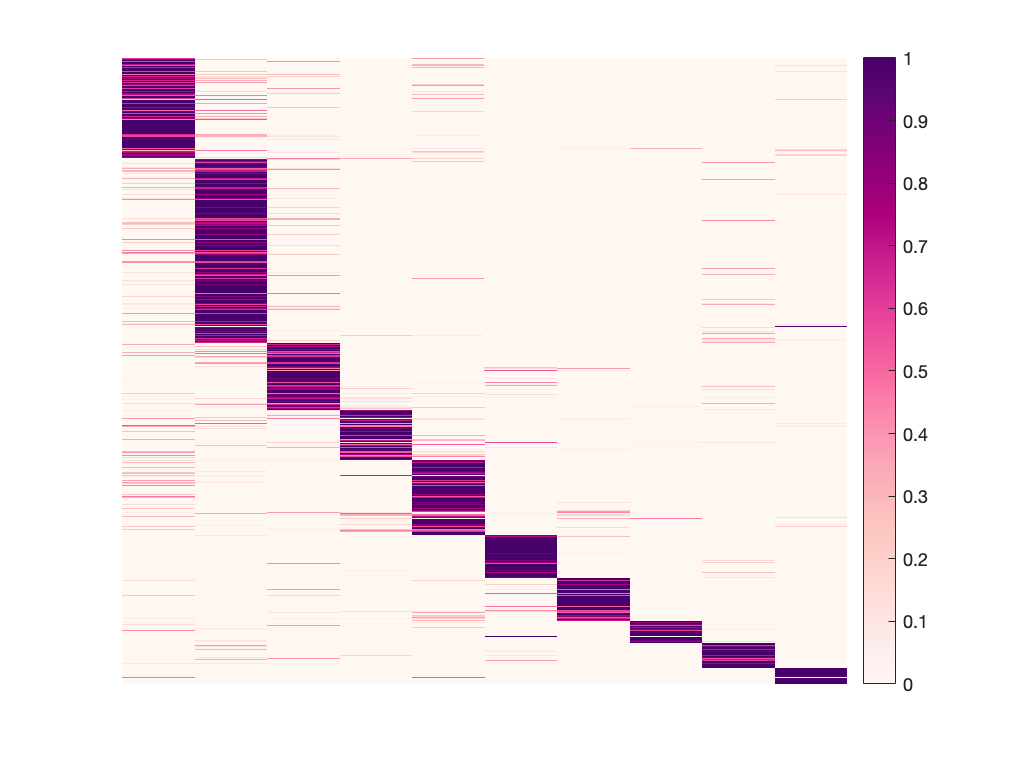


figure;
colormap(brewermap([],cmp))
imagesc(rho_class);
caxis([0 1])
colorbar;
axis off
set(gca,'xtick',[],'ytick',[]);
box off